clear;close all;clc
syms t I A T epsilon lambda n

s(t) = A*sin(t*2*pi/T);
D(t) = (2*pi/lambda)*I^(2)*sin((A*2*pi/lambda)*(sin((2*pi/T*(t-epsilon))) - sin(2*pi*t/T))) * n* lambda

$$D(t) = -2\,\pi \,{\text{I}}^{2}\,n\,\sin\left(\frac{2\,\pi \,A\,\left(\sin\left(\frac{2\,\pi \,t}{T}\right)+\sin\left(\frac{2\,\pi \,\left(\epsilon -t\right)}{T}\right)\right)}{\lambda }\right)$$

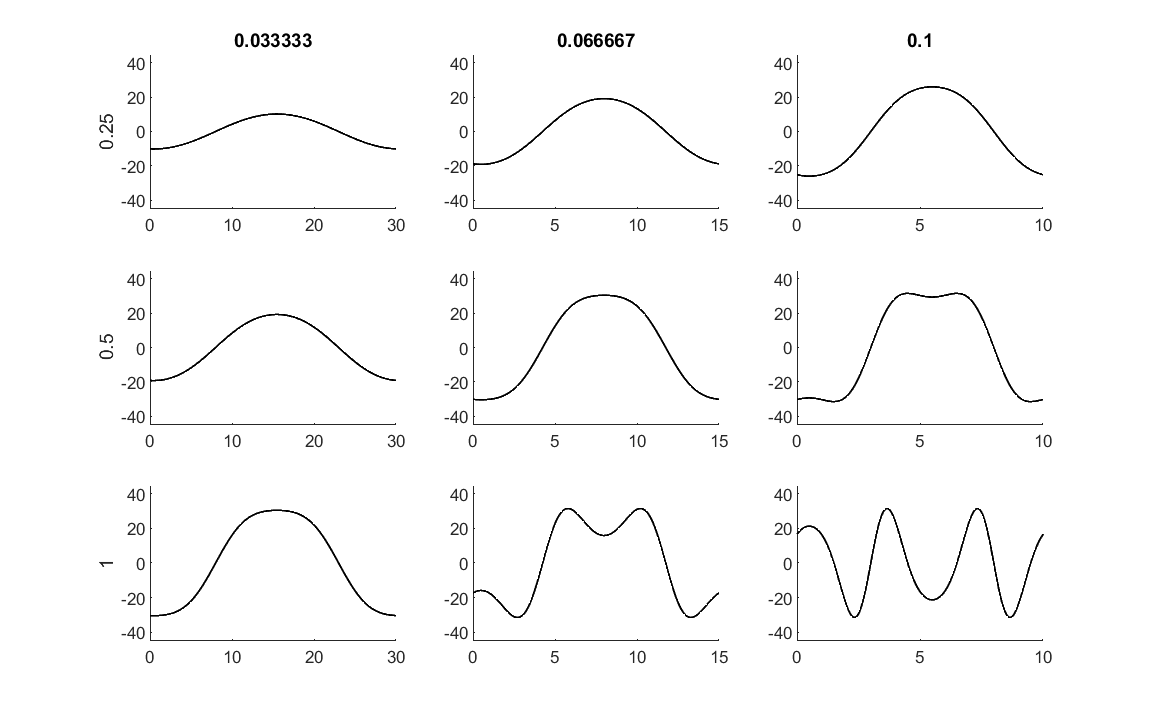

DD =  @(t, I, A, T, epsilon, lambda, n) (2*pi/lambda)*I^(2)*sin((A*2*pi/lambda)*(sin((2*pi/T*(t-epsilon))) - sin(2*pi*t/T)))*n*lambda;

time = linspace(0,50,100000);
n = 5;
lambda = 1;
epsilon = 1;
I = 1;
A = lambda.*[1/4 1/2 1];
T = [30 15 10];
d = cell(length(A),length(T));
for aa = 1:length(A)
    for tt = 1:length(T)
        d{aa,tt} = DD(time,I,A(aa),T(tt),epsilon,lambda,n);
    end
end

FIG = figure (1) ; clf
FIG.Units = 'inches';
FIG.Position = [2 2 8 5];
pp = 1;
for aa = 1:length(A)
    for tt = 1:length(T)
        ax = subplot(length(A),length(T),pp) ; hold on
        plot(time,d{aa,tt},'-k','LineWidth',1)
        xlim([0 T(tt)])
        ylim(45*[-1 1])
        if any(pp==[1 4 7])
            ax.YLabel.String = num2str(A(aa));
            ax.YLabel.FontWeight = 'bold';
        end
        if any(pp==[1:3])
            title(num2str(epsilon/T(tt)))
        end
        pp = pp + 1;
    end
end

clear;close all;clc
syms t I A T epsilon lambda n

s(t) = A*sin(t*2*pi/T)

$$s(t) = A\,\sin\left(\frac{2\,\pi \,t}{T}\right)$$

D(t) = (2*pi/lambda)*I^(2)*sin((A*2*pi/lambda)*(sin((2*pi/T*(t-epsilon))) - sin(2*pi*t/T))) * n* lambda

$$D(t) = -2\,\pi \,{\text{I}}^{2}\,n\,\sin\left(\frac{2\,\pi \,A\,\left(\sin\left(\frac{2\,\pi \,t}{T}\right)+\sin\left(\frac{2\,\pi \,\left(\epsilon -t\right)}{T}\right)\right)}{\lambda }\right)$$

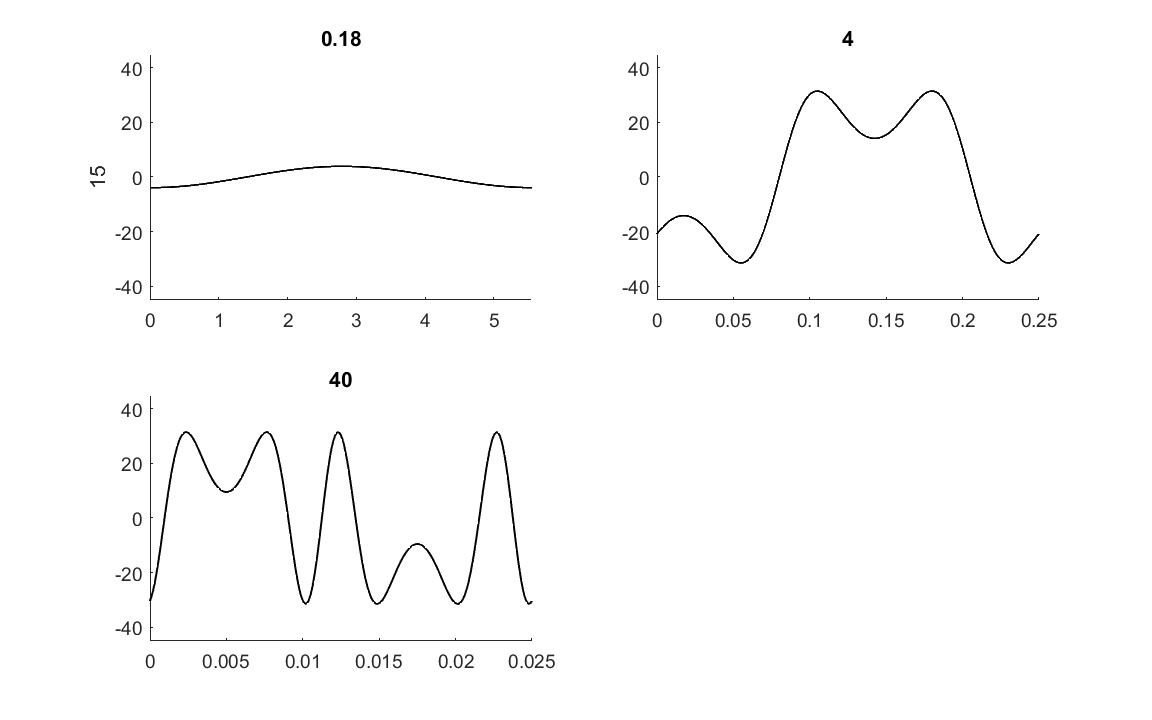

DD =  @(t, I, A, T, epsilon, lambda, n) (2*pi/lambda)*I^(2)*sin((A*2*pi/lambda)*(sin((2*pi/T*(t-epsilon))) - sin(2*pi*t/T)))*n*lambda;
time = linspace(0,10,100000);
n = 5;
lambda = 30;
epsilon = 35e-3;
I = 1;
A = 15;
T = 1./[0.18 4 40];
d = cell(length(A),length(T));
for aa = 1:length(A)
    for tt = 1:length(T)
        d{aa,tt} = DD(time,I,A(aa),T(tt),epsilon,lambda,n);
    end
end

FIG = figure (1) ; clf
FIG.Units = 'inches';
FIG.Position = [2 2 8 5];
pp = 1;
for tt = 1:length(T)
    ax = subplot(ceil(length(T)/2),2,pp) ; hold on
    plot(time,d{aa,tt},'-k','LineWidth',1)
    xlim([0 1*T(tt)])
    ylim(45*[-1 1])
    if any(pp==[1 4 7])
        ax.YLabel.String = num2str(A);
        ax.YLabel.FontWeight = 'bold';
    end
    title(num2str(1/T(tt)))
    pp = pp + 1;
end